Analisis de super posicion para v1

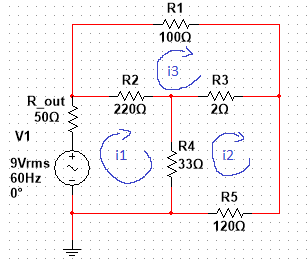

clc, clear, close all
format short g

r_out =50; %[Ω]
r1 = 100; %[Ω]
r2 = 220; %[Ω]
r3 = 330; %[Ω]
r4 = 33; %[Ω]
r5 = 120; %[Ω]

v1 = 9; %[V]

syms i1 i2 i3

m1 = simplify(v1+(r_out*i1)+(r2*(i1-i3))+(r4*(i1-i2))==0)

$$m1 = 33\,i_{2}+220\,i_{3}=303\,i_{1}+9$$

m2 = simplify((r5*i2)+(r4*(i2-i1))+(r3*(i2-i3))==0)

$$m2 = 11\,i_{1}+110\,i_{3}=161\,i_{2}$$

m3 = simplify((r3*(i3-i2))+(r2*(i3-i1))+(r1*i3)==0)

$$m3 = 22\,i_{1}+33\,i_{2}=65\,i_{3}$$

m = [-303 33 220;11 -161 110; 22 33 -65];
n = [9;0;0];
h = m\n;

%corrientes

i1 = h(1,1); %[A]
i2 = h(2,1); %[A]
i3 = h(3,1); %[A]

%potencias

pr_out = ((i1^2)*r_out)*1000 %[mW]

pr_out =        153.99


pr1 = ((i3^2)*r1)*1000 %[mW]

pr1 =        100.53


pr2 = (((i1-i3)^2)*r2)*1000 %[mW]

pr2 =        124.51


pr3 = (((i3-i2)^2)*r3)*1000 %[mW]

pr3 =        12.899


pr4 = (((i1-i2)^2)*r4)*1000 %[mW]

pr4 =        29.783


pr5 = ((i2^2)*r5)*1000 %[mW]

pr5 =        77.752


pv1 = (v1*i1)*1000 %[mW]

pv1 =       -499.47


bp = pr_out+pr1+pr2+pr3+pr4+pr5+pv1

bp =      0



%corriente en cada elemento

ir_out = (i1)*1000 %[mA]

ir_out =       -55.496


ir1 = (i3)*1000 %[mA]

ir1 =       -31.706


ir2 = (i1-i3)*1000 %[mA]

ir2 =        -23.79


ir3 = (i3-i2)*1000 %[mA]

ir3 =        -6.252


ir4 = (i1-i2)*1000 %[mA]

ir4 =       -30.042


ir5 = i2*1000 %[mA]

ir5 =       -25.454


iv1 = i1*1000 %[mA]

iv1 =       -55.496



%tension en cada elemento

vr_out = pr_out/ir_out

vr_out =       -2.7748


vr1 = pr1/ir1

vr1 =       -3.1706


vr2 = pr2/ir2

vr2 =       -5.2338


vr3 = pr3/ir3

vr3 =       -2.0632


vr4 = pr4/ir4

vr4 =      -0.99138


vr5 = pr5/ir5

vr5 =       -3.0545


vv1 = pv1/iv1

vv1 =      9
